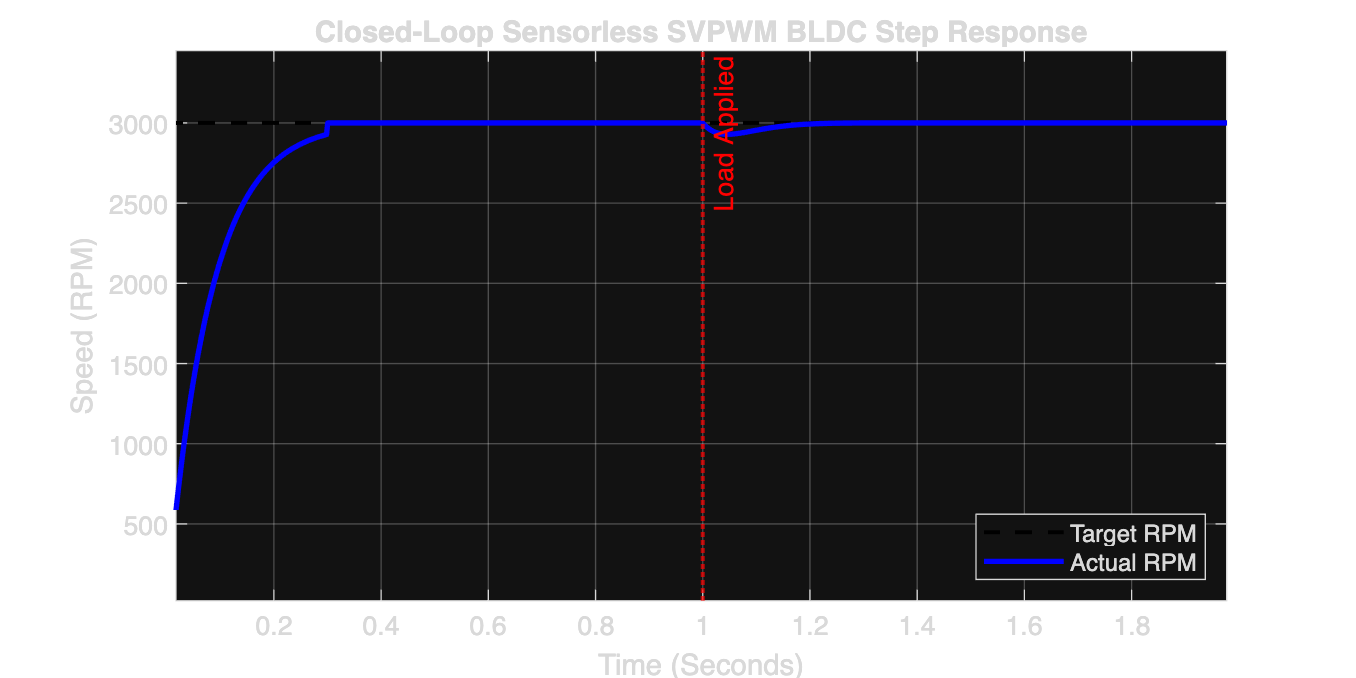

% MATLAB script to generate the closed-loop step response curve
t = linspace(0, 2, 1000);
target_rpm = 3000 * ones(size(t));
actual_rpm = zeros(size(t));

for i = 1:length(t)
    if t(i) < 0.3
        actual_rpm(i) = 3000 * (1 - exp(-t(i)/0.08)); % Startup ramp
    elseif t(i) >= 0.3 && t(i) < 1.0
        actual_rpm(i) = 3000; % Steady state
    elseif t(i) >= 1.0 && t(i) < 1.3
        % Load disturbance dip and PI recovery
        recovery_time = t(i) - 1.0;
        actual_rpm(i) = 3000 - 400 * exp(-recovery_time/0.05) * sin(10 * recovery_time);
    else
        actual_rpm(i) = 3000; % Recovered steady state
    end
end

figure('Color', 'w', 'Position', [100, 100, 800, 400]);
plot(t, target_rpm, 'k--', 'LineWidth', 1.5); hold on;
plot(t, actual_rpm, 'b-', 'LineWidth', 2);
xline(1.0, 'r:', 'LineWidth', 1.5, 'Label', 'Load Applied');
grid on;
title('Closed-Loop Sensorless SVPWM BLDC Step Response');
xlabel('Time (Seconds)');
ylabel('Speed (RPM)');
legend('Target RPM', 'Actual RPM', 'Location', 'Southeast');
ylim([0 3500]);